clc
clear 
close all

defines

load s20/data320.mat
plot(t,y);
hold on
s = tf('s');

analyza

[t_infl,tngt,Tus,Tn] = infp(y,t)

t_infl = 0.3000

tngt =    -0.3857
   -0.2494
   -0.1130
    0.0233
    0.1596
    0.2959
    0.4323
    0.5686
    0.7049
    0.8412


Tus = 0.1415

Tn = 0.5561

Strejco

f_s = Tus/Tn;

%hodnoty odcitane z tabulky deterministicke metody
n_0 = 3;
f_n0 = 0.218;
g_n0 = 0.271;

K = y(end);
D = (f_s - f_n0)*Tn;
T = Tn*g_n0;
F = K/(1+T*s)^n_0*exp(-D*s);
t_model = linspace(0, t(end), 10000);
y_model = step(F,t_model);

plot(t_model, y_model);

Broida

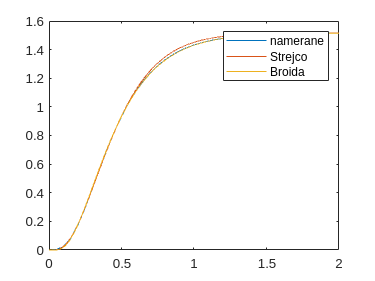

f_s = Tus/Tn;
n_0 = 3;
f_n0 = 0.192;
g_n0 = 0.44;

K = y(end);
D = (f_s - f_n0)*Tn;
T = Tn*g_n0;
F = K / ((T*s + 1)*(T/2*s + 1)*(T/3*s + 1)) * exp(-D*s);
t_model = linspace(0, t(end), 10000);
y_model = step(F,t_model);

plot(t_model, y_model);
legend("namerane","Strejco","Broida")